clear all
load TR4_data.mat
Q=sym("q",[1 3]);
L=sym("l",[1 4]);
J=TR4_jacobian(Q,link);
detJ=det(J);
detJ=matlabFunction(detJ);



## calcolo singolarità

load TR4_data.mat
Sol=[];
point=[];
Q=[];
for q1 = linspace(-Con(1)/2,Con(1)/2,30)
    for q2 = linspace(-Con(2)/2,Con(2)/2,30)
        for q3 = linspace(-Con(3)/2,Con(3)/2,210)
            q=[q1,q2,q3];
            sol=detJ(q1,q2,q3);
            Sol=[Sol sol];
            S = TR4_dirKin(q,link);
            S = S(1:end-1);
            point = [point S];
            Q=[Q q'];
        end
    end
end
save Punti_singolarita point Sol

## Conversione assoluto

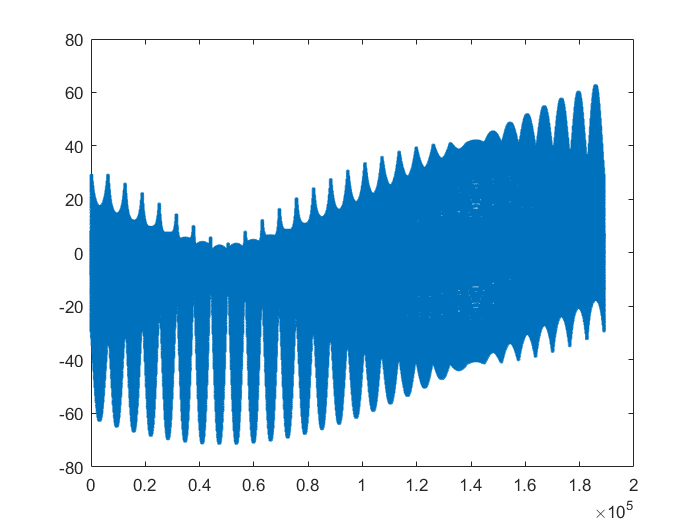

load Punti_singolarita.mat
close all
AbsSol=[];
for s=Sol
    AbsSol=[AbsSol abs(s)];
end
figure
plot(Sol,'.')

save Absolute_Solution AbsSol

## Ricerca singolarità

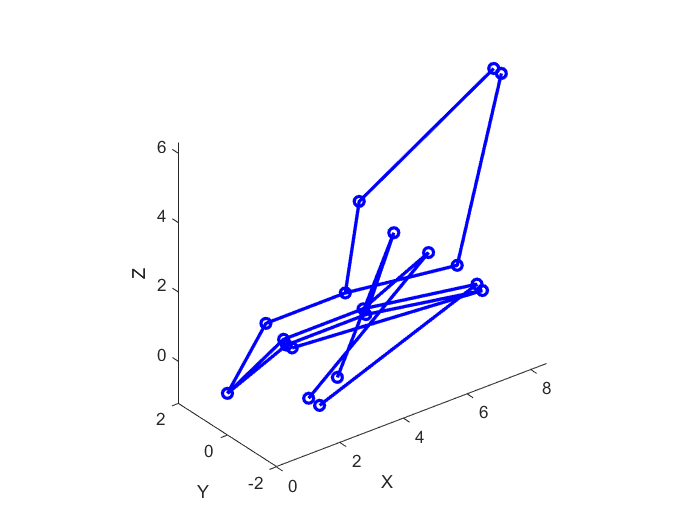

load Punti_singolarita.mat
load Absolute_Solution
close all
sing=[];
figure(2)
for i=1:length(AbsSol)
    el=AbsSol(i);
    if el<0.001
        sing=[sing point(:,i)];
        plot3(point(1,i),point(2,i),point(3,i),'ob')
        hold on
        TR4_plot(Q(:,i)',link,'b',2)
     end
end

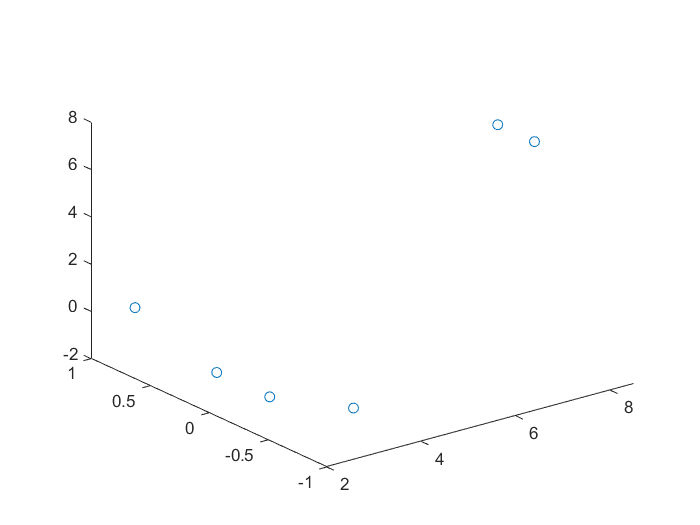

figure
plot3(sing(1,:),sing(2,:),sing(3,:),'o')